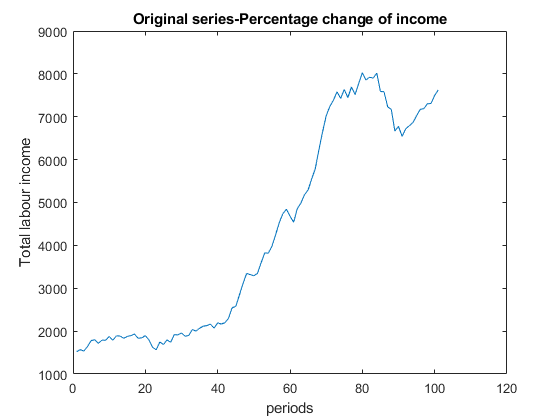

%% Origial Data series
x=income{:,1};
y=income{:,2};
plot(x,y);
title('Original series-Percentage change of income');
xlabel('periods');
ylabel('Total labour income');

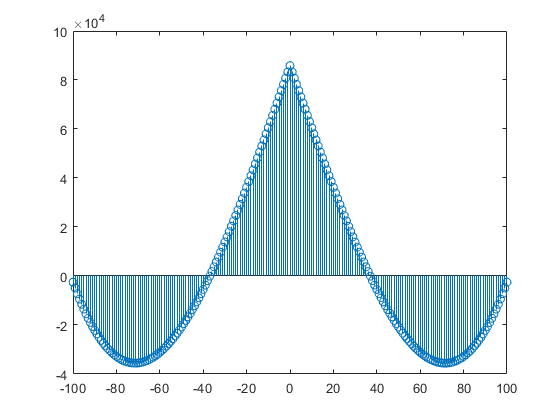


%% Auto-covariance
[c,lags]=xcov(x);
stem(lags,c);



%% OLS model
T0=101;h=4;T=105;
fyhat=zeros(T-h-T0+1,1);
ytph=y(T0+h:end);
for t=T0:T-h
    yt=y(1:t);
    s=(1:t)';
    Xt=[ones(t,1) s s.^2]
    betahat = (x'*x)\(x'*y);
    yhat=[1 t+h (t+h)^2]*betahat;
    fyhat(t-T0+1)=yhat;
end

Xt =      1     1     1
     1     2     4
     1     3     9
     1     4    16
     1     5    25
     1     6    36
     1     7    49
     1     8    64
     1     9    81
     1    10   100


Unable to perform assignment because the left and right sides have a different number of elements.